# AMPC vs. Reactive Controller (Jost Data)

This script compares the adaptive model preditctive controller to the reactive strategy used on patients in Jost et al. 2020. Since the Jost paper seems to dynamically change doses and dosing periods based on a given neutrophil measurement, the ampc method will use the same cycle lengths when determining doses of 6-MP.

TODO: Make another document for more details on procedure

clear all;
clc;
close all;

## Reading from DataSheet

Note: requires Data Sheet 1 and Data Sheet 2 from Jost to be in the same directory as this code. There may be a matlab warning when you read the files but it doesn't affect anything in the file data.

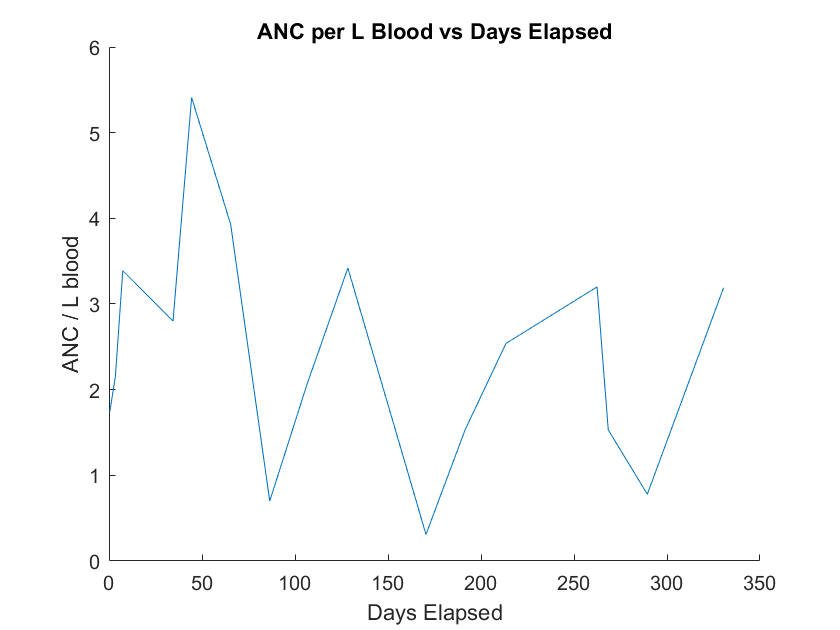

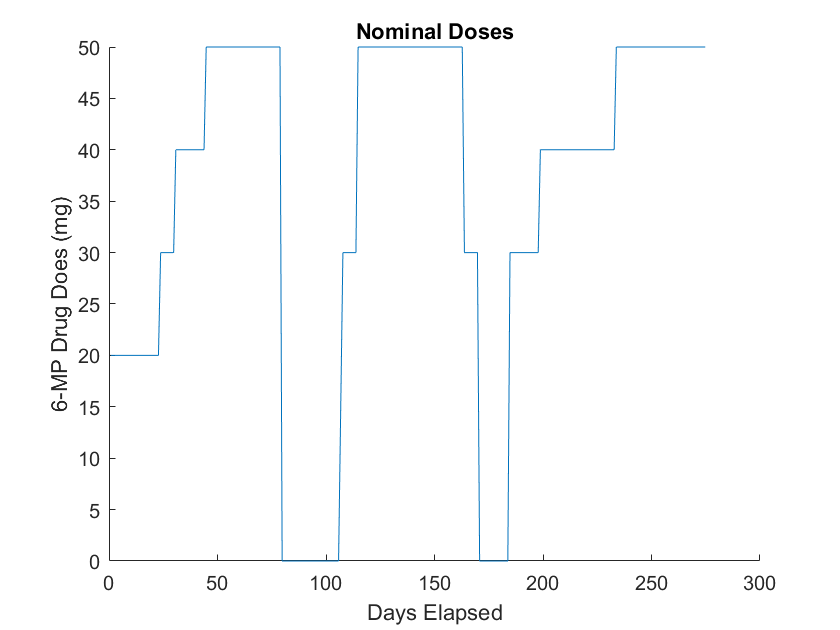

patient_cycles:


Start Time (days) | End Time (days) | Length (days)


    0.7917    2.7917    3.0000
    3.7917    6.7917    4.0000
    7.7917   33.7920   27.0000
   34.7920   43.7920   10.0000
   44.7920   64.7920   21.0000
   65.7920   78.7920   14.0000
   79.7920  106.7900   28.0000
  107.7900  127.7900   21.0000
  128.7900  155.7900   28.0000
  156.7900  169.7900   14.0000
  170.7900  183.7900   14.0000
  184.7900  190.7900    7.0000
  191.7900  212.7900   22.0000
  213.7900  261.7900   49.0000
  262.7900  267.7900    6.0000
  268.7900  274.7900    7.0000



Note that the length is +1 more than it seems because the dose carries onto the next day.


patient_data:


Measurement Time (days) | ANC (10^9 neutrophil cells per litre of blood)


    0.4167    1.7400
    3.4167    2.1500
    7.4167    3.3900
   34.4170    2.8000
   44.4170    5.4100
   65.4170    3.9300
   86.4170    0.7000
  106.4200    2.0600
  128.4200    3.4200
  156.4200    1.3500
  170.4200    0.3100
  191.4200    1.5300
  213.4200    2.5400
  262.4200    3.2000
  268.4200    1.5300
  289.4200    0.7800
  330.4200    3.1900



DataSheet1 = readmatrix("Data Sheet 1.csv");
DataSheet2 = readmatrix("Data Sheet 2.csv");

% Patients are numbered starting from 101 in the datasheet but for
% simplicity only put ids starting from 1 (e.g. patientID 1 in the code corresponds to 101 in datasheet).
% If you enter -1, it uses population instead of patient parameters.
patientID = 6;

% population parameters (from Jost et al.)
population_params = [2.06; 0.146; 0.103; 0.866];
% change however you wish (see note above about theta 6 and 9)
population_params_guess = [2.15; 0.5; 0.25; 0.85]; %[0.75; 1.96; 1.35; 1.75];
population_bsa = 1.71; % Jost 2020 paper (Table 1, Body Surface Area range 0.47-1.98 m^2) - average population BSA

% get patient parameters
if patientID > 0
    p_actual = DataSheet1(patientID, 2:5)'; % turn into 4 by 1
    p_guess = population_params;
    
%     p_actual = [2.06; 0.146; 0.103; 0.866];
%     p_guess = [0.75; 1.96; 1.35; 1.75];
    
    patient_data    = [];
    patient_doses   = [];
    patient_evid    = [];
    patient_cycles  = [];
    simulation_time = [];
    cycle_start_time = 10000; % can be arbitrary because will be overwritten
    last_measurement = true;
    treatment_end_time = -1;
    
    for k=1:length(DataSheet2)
        patient_id  = DataSheet2(k,1);
        time        = DataSheet2(k,2);
        measurement = DataSheet2(k,3);
        dose        = DataSheet2(k,5);
        evid        = DataSheet2(k,7);
        
        if patient_id - 100 == patientID
            bsa = DataSheet2(k,11);
            if measurement ~= 0
                patient_data = [patient_data; time measurement];
                if last_measurement == false
                    patient_cycles = [...
                        patient_cycles;...
                        cycle_start_time ...
                        prev_time ...
                        round(abs(prev_time - cycle_start_time) + 1)];
                    last_measurement = true;
                end
            else
                if last_measurement == true
                    cycle_start_time = time;
                    last_measurement = false;
                    
                    if ~isempty(patient_cycles) && abs(patient_cycles(end,2) - cycle_start_time) > 1
                        % insert a cycle of 0 drug input
                        start_zero_cycle = patient_cycles(end,2) + 1;
                        end_zero_cycle = cycle_start_time - 1;
                        patient_cycles = [...
                            patient_cycles;...
                            start_zero_cycle ...
                            end_zero_cycle ...
                            round(abs(end_zero_cycle - start_zero_cycle) + 1)
                        ];
                        for x=start_zero_cycle:end_zero_cycle
                            patient_doses = [patient_doses; x 0];
                        end
                    end
                end
            end
            if evid
                patient_doses = [patient_doses; time dose];
            end
            patient_evid = [patient_evid; time evid];
            simulation_time = [simulation_time; time];
            treatment_end_time = time;
        end
        
        prev_time = time;
    end
    
    figure()
    hold on
    xlabel('Days Elapsed')
    ylabel('ANC / L blood')
    title("ANC per L Blood vs Days Elapsed")
    plot(patient_data(:,1), patient_data(:,2))
    hold off
    
    figure()
    hold on
    xlabel('Days Elapsed')
    ylabel('6-MP Drug Does (mg)')
    title("Nominal Doses")
    plot(patient_doses(:,1), patient_doses(:,2))
    hold off
    
    disp("patient_cycles:")
    disp("Start Time (days) | End Time (days) | Length (days)")
    disp(patient_cycles);
    disp("Note that the length is +1 more than it seems because the dose carries onto the next day.")
    disp("patient_data:")
    disp("Measurement Time (days) | ANC (10^9 neutrophil cells per litre of blood)")
    disp(patient_data);
else
    p_actual = population_params;
    p_guess = population_params_guess;
    bsa = population_bsa;
end

clear population_bsa population_params_guess population_params
clear patient_id time measurement dose evid


## Initialization

% structure: calc_init_state(theta_6, theat_7, theta_10)
% x0 is the initial state for the virtual patient (from Jost et al.) (REFER TO TABLE IN PAPER)
% theta(6) - which is the Base neutrophil count - is replaced by the initial neutrophil measurement taken from the datasheet
theta_10_init = 2.3765; % from Jost et al. (REFER TO TABLE IN PAPER)
x0 = calc_init_state(patient_data(1,2), p_actual(2), theta_10_init);

% Dimension
n = 8; % dimension of state vector x 
m = 1; % dimension of observation vector y

step_size = 0.02; % units of days

lower = 1; upper = 2; % clinical guidelines (* 10^9 cells per litre blood)

% constraints for dosing plan, drug dose is taken every day (mg of 6-MP per day)
lb_drug = 0.01;
ub_drug = 50*bsa*2; % note: according to Dr. Chan, twice the optimal dose is our upper limit, see line 43 for bsa

% Simulation length based on time vector
t_s = step_size; % units in days
start_time = patient_cycles(1,1);
end_time = patient_cycles(end,2);
N_days = round(abs(start_time-end_time));
N_cycles = size(patient_cycles,1);
N_steps = round(N_days / t_s);
N_steps_per_day = 1 / t_s;
time = (start_time:t_s:end_time + t_s);

## Nominal Trajectory

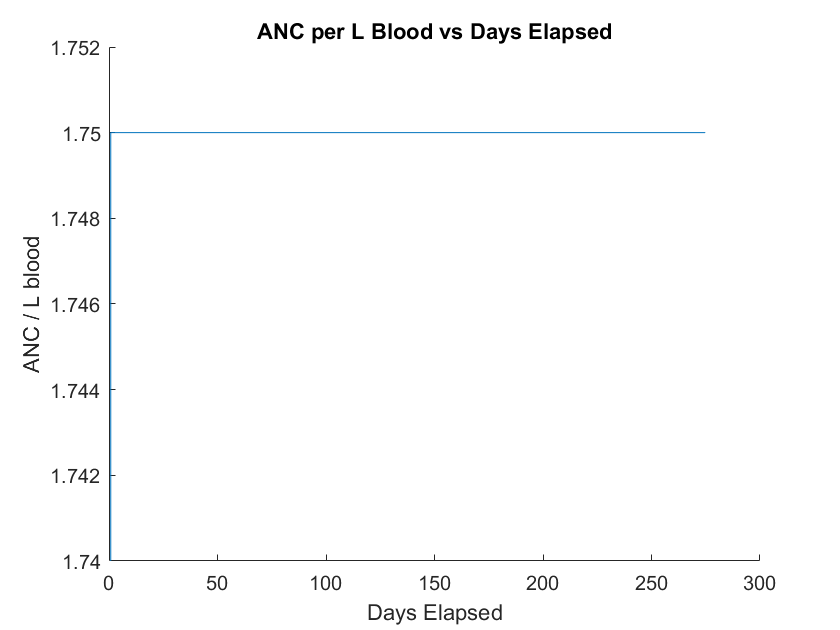

u_nominal = zeros([N_steps 1]); % nominal trajectory for the drug (6-MP doses)
rho = ones([N_steps+1 1]) * 1.75; % nominal trajectory for neutrophils is just a setpoint

u_k=50*bsa;
rho(1,:) = g_nonlin(x0);
cycle_index = 1;

for k=1:N_days
    cycle_length = patient_cycles(cycle_index, 3);
    day_in_cycle = get_cycle_day(k, cycle_length);
    for i=1:N_steps_per_day
        j = (N_steps_per_day*(k-1) + i);
        % for comparison with Jost data, drug is administered everyday
        % maybe add ability to handle off-drug periods for different kinds of data
        u_nominal(j,:) = u_k;
    end
    % currently not being used because we want the neutrophils to be at a setpoint at this stage in the research
    % in the future, we may want u_nominal to be a sinusoid centered at the setpoint to improve parameter estimation
    if day_in_cycle == cycle_length
        x_k8 = rho(j+1,:);
        if x_k8 < lower
            u_k = 0.8*u_k;
        elseif x_k8 > upper
            u_k = 1.2*u_k;
        end
    end
end

figure()
hold on
xlabel('Days Elapsed')
ylabel('ANC / L blood')
title("ANC per L Blood vs Days Elapsed")
plot(time,rho)
hold off

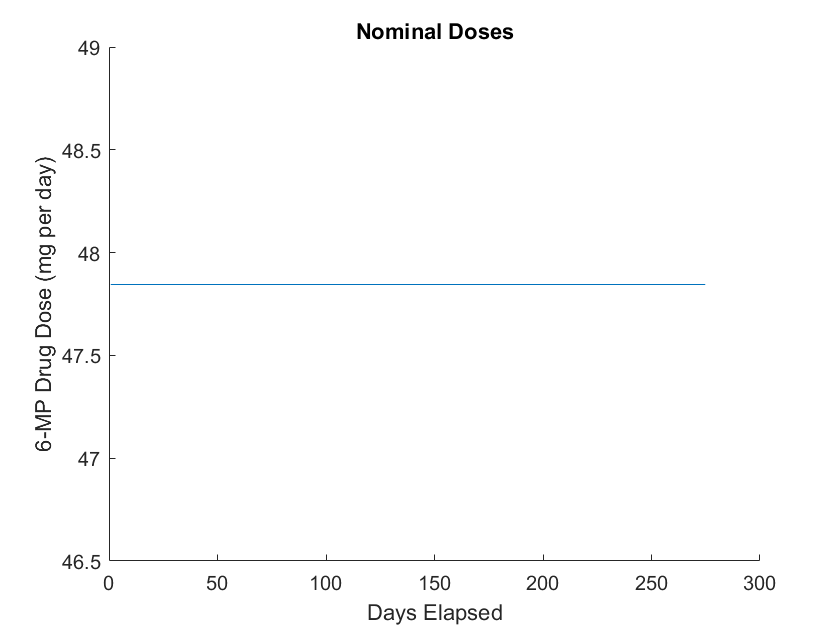


figure()
hold on
xlabel('Days Elapsed')
ylabel('6-MP Drug Dose (mg per day)')
title("Nominal Doses")
plot(time(:,1:end-1),u_nominal)
hold off

## Adaptive Model Predictive Controller

% This is how many cycles ahead we want to predict, usually increasing this
% results in better performance but longer runtimes
N_cyclespred = 5;

n_params = length(p_actual);
x_calc = []; % calculated state of virtual patient using controller and Jost model
y_calc = []; % calculated measurement (neutrophil concentration) of virtual patient
past_measurements = []; % the "measurements" for virtual patient
params_calc = []; % estimated parameters for every cycle for the virtual patient
u_calc = zeros([1,N_days]); % calculated optimal 6-MP drug dose for virtual patient

x_calc(:,:,1) = x0; % 8 by 1 by number of steps
y_calc(:,:,1) = g_nonlin(x0); % 1 by 1 by number of steps
params_calc(:,:,1) = p_guess; % 4 by 1 by number of cycles
past_measurements(:,:,1) = [y_calc(:,:,1); 1; patient_data(1,1)]; % 3 by 1 by number of measurements
% [measurement value; index of y_calc that has the measurement; the global time when measurement is taken] 
% this vector is used to plot the stars in the neutrophil concentration figure

cycle = 1;
k = 0;

while k < N_days && cycle <= N_cycles
    prev_step_idx = size(x_calc,3); % helps get last calculated state
    N_cycledays = patient_cycles(cycle,3); % the number of days in this cycle
    N_drugdays = N_cycledays; % for Jost data there are no off drug days. For Steve's data this line would change
    
    % This part gets the parameter estimation
    % Here, we recalculate the initial state using the previously calculated parameter estimates
    % This is our preliminary attempt to create an observer for x0
    x0_estimate = calc_init_state(params_calc(1,1,cycle), params_calc(2,1,cycle), theta_10_init);
    f = @(p)calc_params_comparison(past_measurements, p, x0_estimate, u_calc, prev_step_idx, N_cycledays, N_cycledays, t_s);
    [p_star, fval] = fmincon(...
        f,params_calc(:,:,cycle), [], [], [], [], ...
        repmat(0.001, [size(params_calc, 1) 1]), ...
        repmat(5.00, [size(params_calc, 1) 1]) ...
    );
    
    % This part gets the optimal 6-MP dose using p_star
    % IMPORTANT NOTE: x_calc(:,:,prev_step_idx) is calculated using the true parameter vector and optimized
    % control input (the state of the virtual patient at this time) but in practice we would not have access 
    % to the full state. So an important step in the future is to use the past measurements to estimate the 
    % full state of the patient at this time (aka make an observer).
    x_k = x_calc(:,:,prev_step_idx); 
    if k == 0 % we are only using our "observer" for the initial state because we don't have one for the future states
        x_k = x0_estimate;
    end
    g = @(u)calc_control_comparison(...
        p_star, rho, x_k, k, cycle, u, 10, 0.0001, ...
        N_cyclespred, N_cyclespred, patient_cycles, t_s ...
    );
    init_guess_u = 50*bsa;
    [u_star, gval] = fmincon(...
        g,repmat(init_guess_u, [N_cyclespred 1]), [], [], [], [], ...
        repmat(lb_drug, [N_cyclespred 1]), ...
        repmat(ub_drug, [N_cyclespred 1]) ...
    );
    
    % Here we perform our updates for control, parameters and states for our virtual patient
    u_calc(k+1:k+N_drugdays) = u_star(1);
    params_calc(:,:,cycle+1) = p_star;

    if cycle == 6
        disp("reached")
    end
    
    for i=prev_step_idx:prev_step_idx + N_steps_per_day*N_cycledays - 1
        % Calculating the state updates for the virtual patient using
        % u_star and p_actual (the real parameter vector)
        x_calc(:,:,i+1) = jost_discrete((i+1)*t_s,x_calc(:,:,i), u_calc(k+1),p_actual,N_cycledays,N_drugdays,t_s);
        y_calc(:,:,i+1) = g_nonlin(x_calc(:,:,i+1));
        
        % Here, we get the timestep that occurs right before the actual time
        % Note: this assumes that a measurement is taken at the start of
        % each cycle but for example for Patients 102-105 in the Jost dataset,
        % there isn't a measurement at the start of treatment so the
        % algorithm breaks
        %if patient_data(size(past_measurements,3)+1,1) < time(:, prev_step_idx + N_steps_per_day*N_cycledays - 1)
        
        if i+1 > size(time, 2)
            continue
        end
        time_diff = patient_data(size(past_measurements,3)+1,1) - time(:,i+1);
        if time_diff < 0 % the moment the difference goes negative, the actual closest timestep is step right before
            % Debugging: Print actual measurement time vs. simulation time
            % fprintf("%d %d\n",patient_data(cycle+1,1),time(:,i))
            
            % We store the measurement, index and time (in days) to use in calc_control_comparison()
            past_measurements(:,:,end+1) = [y_calc(:,:,i); i; time(:,i)];
        end
        %end
    end
    
    cycle = cycle + 1;
    k = k + N_cycledays;    
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


reached



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Plots

Plots look really bad in the default viewer because of the font size, open all figures in new window and fix any bad styling for documents

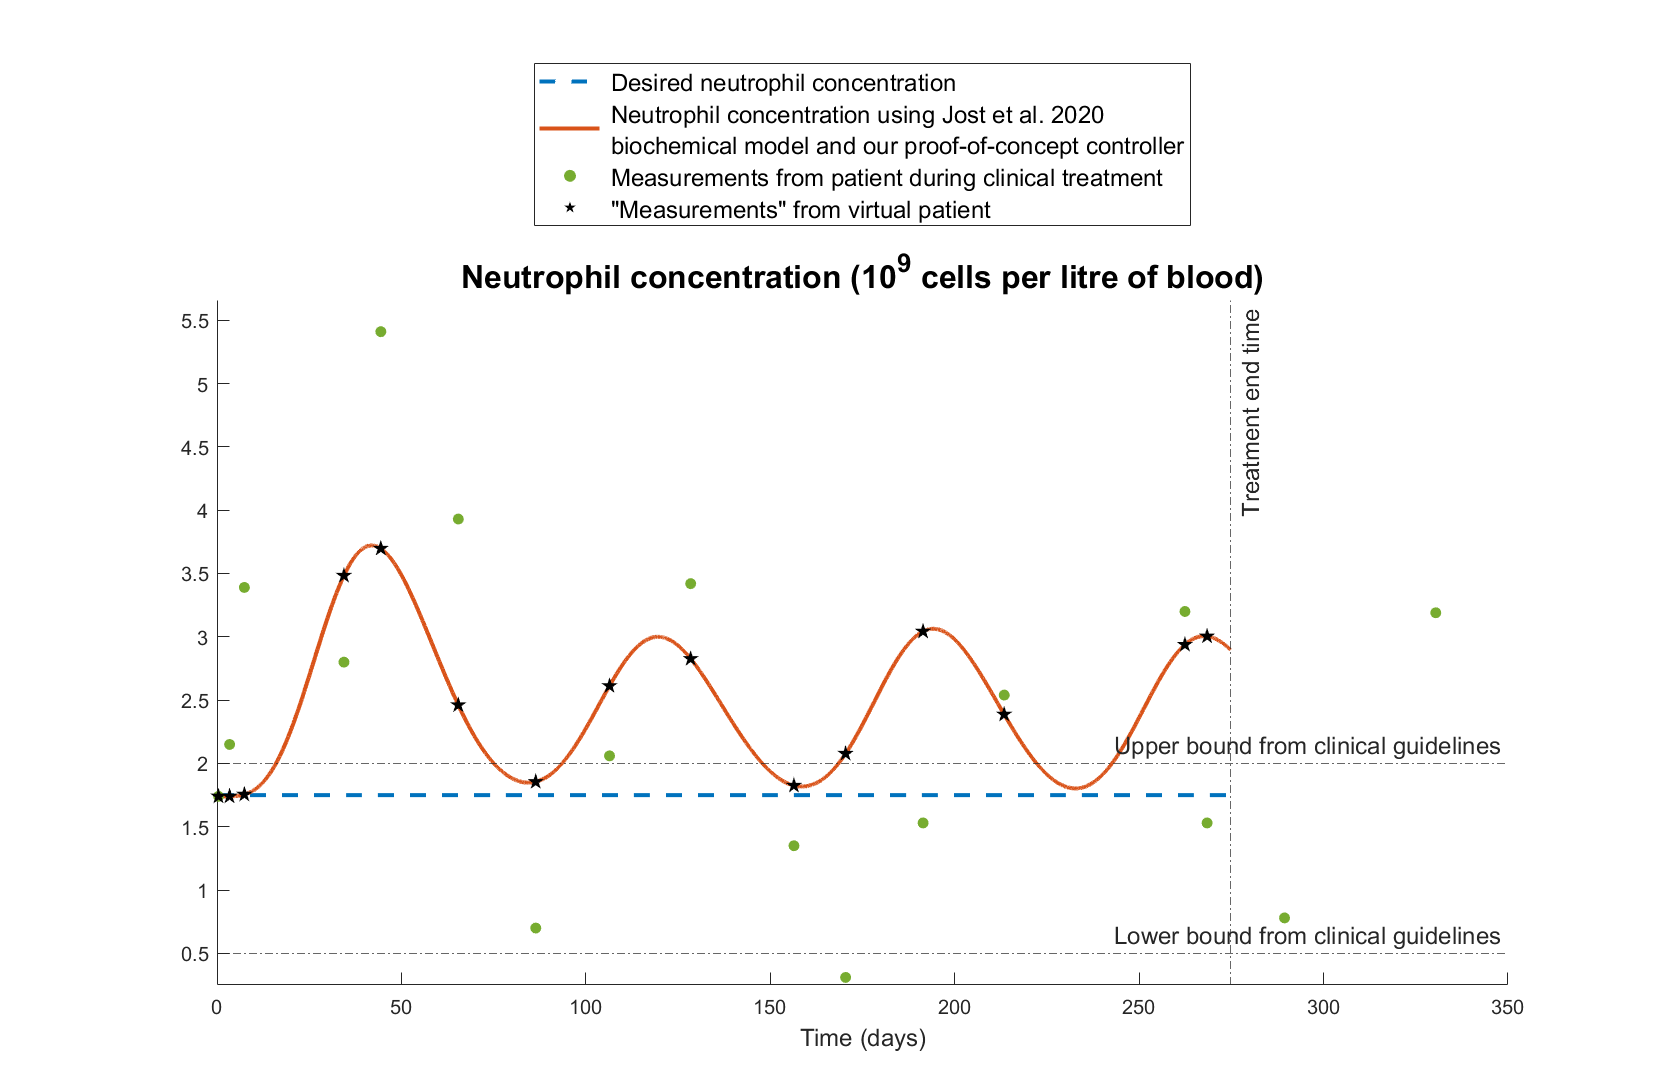

u_calc_full = zeros(size(u_nominal));
for k=1:N_days
    i = N_steps_per_day*(k-1);
    u_calc_full(i+1:i+N_steps_per_day,:) = u_calc(k)*(ones(N_steps_per_day,1));
end
y_neutrophils = reshape(y_calc(1,1,:),[1 size(y_calc, 3)]);

neutrophils_fig = figure('Position', [0,0,1500,970]);
hold on

% Plotting data
plot(time,rho, "LineStyle","--", "LineWidth", 2)
plot(time, y_neutrophils(1:length(time)), "LineWidth", 2)
scatter(patient_data(:,1), patient_data(:,2), 30, [0.4660 0.6740 0.1880], "filled")
scatter(past_measurements(3,:,:), past_measurements(1,:,:), 75, "black", "filled", "pentagram")

% Styling and Text
title('Neutrophil concentration (10^9 cells per litre of blood)', "FontSize", 16)

ub = yline(2, "-.", "Upper bound from clinical guidelines");
lb = yline(0.5, "-.", "Lower bound from clinical guidelines");
ub.FontSize = 12;
lb.FontSize = 12;

end_line = xline(patient_cycles(end,2), '-.', "Treatment end time");
end_line.FontSize = 12;

ylim([0.25 max(patient_data(:,2)) + 0.25])
xlabel('Time (days)', "FontSize", 12)

lgd1 = legend(...
    ' Desired neutrophil concentration',...
    sprintf(' Neutrophil concentration using Jost et al. 2020\n biochemical model and our proof-of-concept controller'),...
    ' Measurements from patient during clinical treatment',...
    ' "Measurements" from virtual patient'...
);
lgd1.Location = "northoutside";
lgd1.FontSize = 12;

hold off

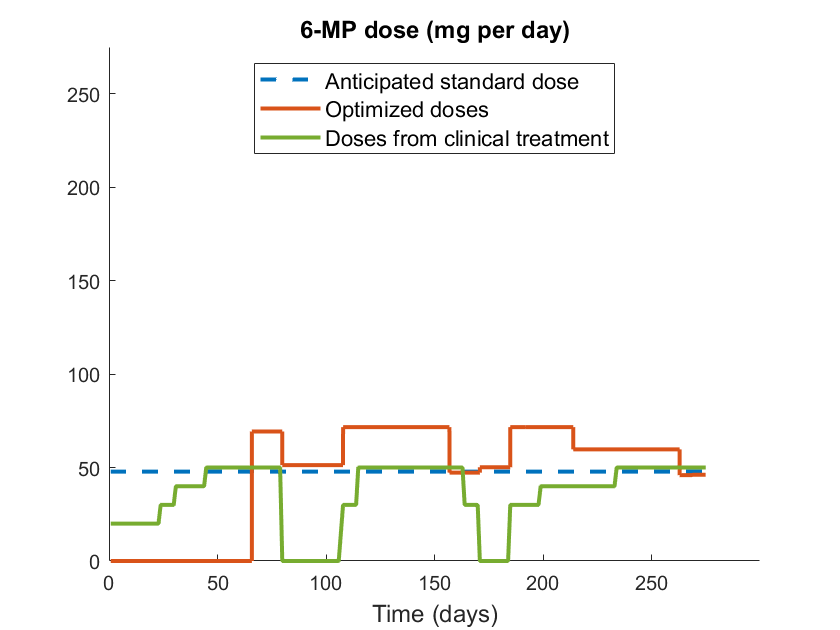

doses_fig = figure();
hold on

plot(time(:,1:end-1),u_nominal, "LineStyle", "--", "LineWidth", 2)
plot(time(:,1:end-1),u_calc_full, "LineWidth", 2)
plot(patient_doses(:,1), patient_doses(:,2), "Color", "#77AC30", "LineWidth", 2)

title('6-MP dose (mg per day)', "FontSize", 12)
xlabel('Time (days)', "FontSize", 12)
ylabel('')
ylim([0 275])
xlim([0 patient_cycles(end,2) + 25])
l = legend('Anticipated standard dose','Optimized doses','Doses from clinical treatment');
l.Location = "north";
l.FontSize = 11;
gca.FontSize = 12;

hold off

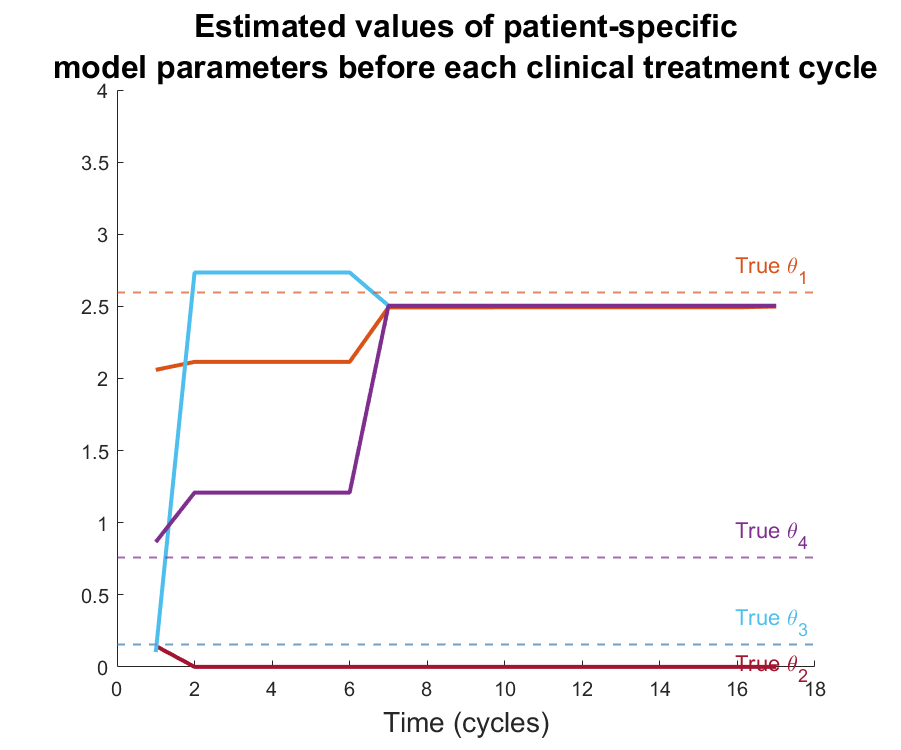


p1 = reshape(params_calc(1,1,:),[1 cycle]);
p2 = reshape(params_calc(2,1,:),[1 cycle]);
p3 = reshape(params_calc(3,1,:),[1 cycle]);
p4 = reshape(params_calc(4,1,:),[1 cycle]);

params_fig = figure('Position',[0,0,600,500]);
hold on

plot(p1, "LineWidth", 2, "Color", "#D95319")
plot(p2, "LineWidth", 2, "Color", "#A2142F")
plot(p3, "LineWidth", 2, "Color", "#4DBEEE")
plot(p4, "LineWidth", 2, "Color", "#7E2F8E")

base_line = yline(p_actual(1), "--", "True \theta_1", "Color", "#D95319");
ktr_line = yline(p_actual(2), "--", "True \theta_2", "Color", "#A2142F");
slope_line = yline(p_actual(3), "--", "True \theta_3", "Color", "#4DBEEE");
gamma_line = yline(p_actual(4), "--", "True \theta_4", "Color", "#7E2F8E");

base_line.LineWidth = 1;
ktr_line.LineWidth = 1;
slope_line.LineWidth = 1;
gamma_line.LineWidth = 1;

base_line.FontSize = 11;
ktr_line.FontSize = 11;
slope_line.FontSize = 11;
gamma_line.FontSize = 11;

ktr_line.LabelVerticalAlignment = "bottom";

ylim([0, 4]);

title(...
    sprintf('Estimated values of patient-specific\nmodel parameters before each clinical treatment cycle'),...
    "FontSize", 16 ...
);

xlabel('Time (cycles)', "FontSize", 14)
ylabel('')
% Uncomment for legend
% lgd2 = legend(...
%     sprintf('%s - Expected to be %0.3f', "\theta_1", p_actual(1)), ...
%     sprintf('%s - Expected to be %0.3f', "\theta_2",p_actual(2)), ...
%     sprintf('%s - Expected to be %0.3f', "\theta_3",p_actual(3)), ...
%     sprintf('%s - Expected to be %0.3f', "\theta_4",p_actual(4)) ...
% );
% ldg2.Location = "northoutside";
% lgd2.FontSize = 14;
gca.FontSize = 12;

hold off

#### Save figures to png in same folder named "patient_x_plots"

root = fileparts(matlab.desktop.editor.getActiveFilename);
new_folder = sprintf("%s\\patient_%d_plots", root, patientID);
mkdir(new_folder);

n_filename = fullfile(new_folder, "neutrophils.png");
d_filename = fullfile(new_folder, "doses.png");
p_filename = fullfile(new_folder, "params.png");
exportgraphics(neutrophils_fig, n_filename, "ContentType", "image");
exportgraphics(doses_fig, d_filename, "ContentType", "image");
exportgraphics(params_fig, p_filename, "ContentType", "image");

#### Putting it all in one figure and saving it in the same folder as created above

all_figs = figure("Name", sprintf("All Figures for Patient %d", patientID), "Position", [0,0,1200,400]);
axes_font_size = 12;
use_legend = true;

% ------------------------------ NEUTROPHIL PLOT --------------------------------------------
subplot(1,10,[1 2 3 4])
hold on

plot(time,rho, "LineStyle","--", "LineWidth", 2)
plot(time, y_neutrophils, "LineWidth", 2)
scatter(patient_data(:,1), patient_data(:,2), 30, [0.4660 0.6740 0.1880], "filled")
scatter(past_measurements(3,:,:), past_measurements(1,:,:), 75, "black", "filled", "pentagram")

yline(2, "-.");
yline(0.5, "-.");
xline(patient_cycles(end,2), '-.');
ylim([0.25 max(patient_data(:,2)) + 0.25])

xlabel('Time (days)', "FontSize", axes_font_size)
ylabel('ANC (10^9 cells/L blood)', "FontSize", axes_font_size)

if use_legend
    lgd = legend(...
        ' Desired neutrophil concentration',...
        sprintf(' Neutrophil concentration using Jost et al. 2020\n biochemical model and our proof-of-concept controller'),...
        ' Measurements from patient during clinical treatment',...
        ' "Measurements" from virtual patient'...
    );
    lgd.Location = "northoutside";
    lgd.FontSize = 8;
end
hold off

% ------------------------------ 6-MP DOSE PLOT --------------------------------------------
subplot(1,10,[5 6 7])
hold on

plot(time(:,1:end-1),u_nominal, "LineStyle", "--", "LineWidth", 2)
plot(time(:,1:end-1),u_calc_full, "LineWidth", 2)
plot(patient_doses(:,1), patient_doses(:,2), "Color", "#77AC30", "LineWidth", 2)

xlabel('Time (days)', "FontSize", axes_font_size)
ylabel('6-MP dose (mg/day)', "FontSize", axes_font_size)
xlim([0 patient_cycles(end,2) + 25])

if use_legend
    l = legend('Anticipated standard dose','Optimized doses','Doses from clinical treatment');
    l.Location = "northoutside";
    l.FontSize = 8;
end
hold off

% --------------------------- PARAMETER ESTIMATION PLOT -------------------------------------
subplot(1,10,[8 9 10])
hold on

plot(p1, "LineWidth", 2, "Color", "#D95319")
plot(p2, "LineWidth", 2, "Color", "#A2142F")
plot(p3, "LineWidth", 2, "Color", "#4DBEEE")
plot(p4, "LineWidth", 2, "Color", "#7E2F8E")

base_line = yline(p_actual(1), "--", "True \theta_1", "Color", "#D95319", "LineWidth", 1);
ktr_line = yline(p_actual(2), "--", "True \theta_2", "Color", "#A2142F", "LineWidth", 1);
slope_line = yline(p_actual(3), "--", "True \theta_3", "Color", "#4DBEEE", "LineWidth", 1);
gamma_line = yline(p_actual(4), "--", "True \theta_4", "Color", "#7E2F8E", "LineWidth", 1);

ktr_line.LabelVerticalAlignment = "middle";

xlabel('Time (cycles)', "FontSize", axes_font_size)
ylabel('Parameter Estimation', "FontSize", axes_font_size)

if use_legend
    lgd = legend(...
        sprintf('%s - Neutrophil count baseline', "\theta_1"), ...
        sprintf('%s - Inter-compartmental transfer rate', "\theta_2"), ...
        sprintf('%s - PD effect slope parameter', "\theta_3"), ...
        sprintf('%s - Feedback parameter', "\theta_4") ...
    );
    lgd.Location = "northoutside";
    lgd.FontSize = 8;
end
hold off

all_figs_filename = fullfile(new_folder, sprintf("patient%d.png", patientID));
exportgraphics(all_figs, all_figs_filename, "ContentType", "image");